syms theta1 theta1_dot theta1_ddot theta2 theta2_dot theta2_ddot
syms t0 t1 t

m1=1; m2=1; l1= 1; l2 = 1; r1 = 0.45; r2= 0.45; I1=0.084; I2=0.084; g = 9.81;
m1_new = 0.75 ;m2_new = 0.75 ; i1_new = 0.063 ; i2_new = 0.063 ;

to = 0; tf = 10;
%Cubic Polynomial

%For Joint 1 
A1 =  [1 t0 t0^2 t0^3;
      0 1 2*t0 3*t0^2;
      1 t1 t1^2 t1^3;
      0 1 2*t1 3*(t1^2)]

$$A1 = \left[\begin{array}{cccc} 1 & t_{0} & {t_{0}}^{2} & {t_{0}}^{3}\\ 0 & 1 & 2\,t_{0} & 3\,{t_{0}}^{2}\\ 1 & t_{1} & {t_{1}}^{2} & {t_{1}}^{3}\\ 0 & 1 & 2\,t_{1} & 3\,{t_{1}}^{2} \end{array}\right]$$

B1 = [pi ; 0 ; 0 ; 0]

B1 =     3.1416
         0
         0
         0




J1 = inv(A1)*B1

$$J1 = \left[\begin{array}{c} \frac{\pi \,\left(-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}\right)}{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}}\\ -\frac{6\,\pi \,t_{0}\,t_{1}}{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}}\\ \frac{3\,\pi \,\left(t_{1}+t_{0}\right)}{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}}\\ -\frac{2\,\pi }{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}} \end{array}\right]$$


%For Joint 2 
B2 = [pi/2 ; 0 ; 0 ; 0]

B2 =     1.5708
         0
         0
         0


J2 = inv(A1)*B2

$$J2 = \left[\begin{array}{c} \frac{\pi \,\left(-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}\right)}{2\,\left(-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}\right)}\\ -\frac{3\,\pi \,t_{0}\,t_{1}}{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}}\\ \frac{3\,\pi \,\left(t_{1}+t_{0}\right)}{2\,\left(-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}\right)}\\ -\frac{\pi }{-{t_{1}}^{3}+3\,t_{0}\,{t_{1}}^{2}-3\,{t_{0}}^{2}\,t_{1}+{t_{0}}^{3}} \end{array}\right]$$

% 
%Trajectories of the following joints 
%Joint 1
Joint1 = [1 t t^2 t^3]*J1;
vel1 = jacobian(Joint1,t);
acc1 = jacobian(vel1,t);

%Joint2
Joint2 = [1 t t^2 t^3]*J2;
vel2 = jacobian(Joint2,t);
acc2 = jacobian(vel2,t);

v = [theta1_ddot;theta2_ddot];

%State Space Equations
X = [ theta1;theta2;theta1_dot;theta2_dot]

$$X = \left[\begin{array}{c} \theta_{1}\\ \theta_{2}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}} \end{array}\right]$$


dX = [X(3); X(4); v(1); v(2)] %not change

$$dX = \left[\begin{array}{c} \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ \theta_{\ddot{1}}\\ \theta_{\ddot{2}} \end{array}\right]$$


A = jacobian(dX,X);
A = double(A)

A =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


B = jacobian(dX,v);
B = double(B)

B =      0     0
     0     0
     1     0
     0     1



% CONTRALLIBILITY MATRIX
Con = ctrb(A,B);
rank(Con);


%EIGEN VALUE PLACEMENT TO CHOOSE K VALUES
lamdas = [-1, -1, -2, -2]

lamdas =     -1    -1    -2    -2



K = place(A,B,lamdas)

K =     2.0000         0    3.0000         0
         0    2.0000         0    3.0000



%increasing q results in a more aggrressive system.
Q = eye(4)*10

Q =     10     0     0     0
     0    10     0     0
     0     0    10     0
     0     0     0    10


Acl = [ 0 0 1 0; 0 0 0 1; -K]

Acl =          0         0    1.0000         0
         0         0         0    1.0000
   -2.0000         0   -3.0000         0
         0   -2.0000         0   -3.0000


P = lyap(Acl',Q)

P =    12.5000         0    2.5000         0
         0   12.5000         0    2.5000
    2.5000         0    2.5000         0
         0    2.5000         0    2.5000



% CALLING ODE FUNCTION
rho = 8;
phi = 0.1;

init = [deg2rad(200), deg2rad(125), 0, 0];
[t, y] = ode45(@(t,y) ode_rrbot2(t,y,P,K,phi,rho), [0, 10], init);
%Desired trajectories
int  = 0:0.1:10;

% Trajectory for Joint 1
Joint1 = (pi*int.^3)/500 - (3*pi*int.^2)/100 + pi;
des_vel1 = (3*pi*int.^2)/500 -(3*pi*int)/50;
des_acc1 = (3*pi*int)/250 -(3*pi)/50;

% Trajectory for Joint 2
Joint2 = (pi*int.^3)/1000 - (3*pi*int.^2)/200 + pi/2;
des_vel2 = (3*pi*int.^2)/1000 -(3*pi*int)/100;
des_acc2 = (3*pi*int)/500 -(3*pi)/100;

% Expected/Experimental Values 
taus = [];


for i=1:length(t)
    
    %Expected Values
    exp_theta1 = y(i,1);
    exp_theta2 = y(i,2);
    exp_theta1_dot = y(i,3);
    exp_theta2_dot = y(i,4);

    %Desired values
    des_theta1 = (pi*t(i).^3)/500 - (3*pi*t(i).^2)/100 + pi;
    des_theta2 = (pi*t(i).^3)/1000 - (3*pi*t(i).^2)/200 + pi/2;
    des_theta1_dot = (3*pi*t(i).^2)/500 - (3*pi*t(i))/50;
    des_theta2_dot = (3*pi*t(i).^2)/1000 - (3*pi*t(i))/100;
    des_acc1 = (3*pi*t(i))/250 - (3*pi)/50;
    des_acc2 = (3*pi*t(i))/500 - (3*pi)/100;
    net_acc = [des_acc1;des_acc2];
    
 
    %Constants 
    i1_new = 0.063 ; i2_new = 0.063 ; m1_new=0.75 ; m2_new = 0.75 ;
    a = i1_new + i2_new + m1_new*r1^2 + m2_new*(l1^2 + r2^2);
    b = m2_new*l1*r2;
    d = i2_new + m2_new*r2^2;

    % M_mat, C_mat and G_mat from the Assignment 
    M_mat = [a+2*b*cos(exp_theta2), d+b*cos(exp_theta2); d+b*cos(exp_theta2), d];
    C_mat = [-b*sin(exp_theta2)*exp_theta2_dot, -b*sin(exp_theta2)*(exp_theta1_dot+exp_theta2_dot); b*sin(exp_theta2)*exp_theta1_dot,0];
    G_mat = [-m1_new*g*r1*sin(exp_theta1)-m2_new*g*(l1*sin(exp_theta1)+r2*sin(exp_theta1+exp_theta2)); -m2_new*g*r2*sin(exp_theta1+exp_theta2)];
    error = [exp_theta1;exp_theta2;exp_theta1_dot;exp_theta2_dot]-[des_theta1;des_theta2;des_theta1_dot;des_theta2_dot];
    
    %Boundary Condition 
    if phi > 0
        if norm((error')*P*B) > phi
                vr = -rho*((error')*P*B)/(norm((error')*P*B));
        else
                vr = -rho*((error')*P*B)/(phi);
        end
    else
       if norm((error')*P*B) ~= 0
                vr = -rho*((error')*P*B)/(norm((error')*P*B));
        else
                vr = [0 0] ;
       end
     end
    
    des_v = net_acc - (K * ([exp_theta1;exp_theta2;exp_theta1_dot;exp_theta2_dot]-[des_theta1;des_theta2;des_theta1_dot;des_theta2_dot])) + vr';
    
    des_u =  M_mat*des_v + C_mat*[exp_theta1_dot;exp_theta2_dot] + G_mat ;
    taus = [taus; des_u(1) des_u(2)];
end


disp("MATLAB TRAJECTORIES");

MATLAB TRAJECTORIES


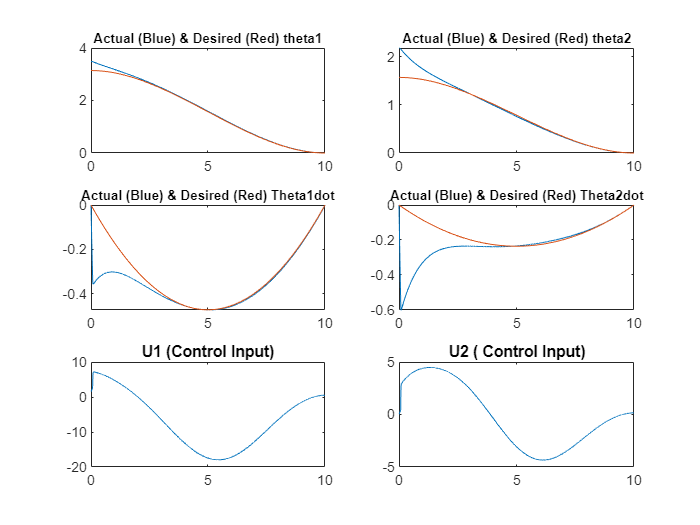


subplot(3,2,1)
plot(t,y(:,1))
hold on
plot(int ,Joint1)
hold off
title('Actual (Blue) & Desired (Red) theta1',fontsize=8)

subplot(3,2,2)
plot(t,y(:,2))
hold on
plot(int ,Joint2)
hold off
title('Actual (Blue) & Desired (Red) theta2',fontsize=8)

subplot(3,2,3)
plot(t,y(:,3))
hold on
plot(int ,des_vel1)
hold off
title('Actual (Blue) & Desired (Red) Theta1dot',fontsize=8)

subplot(3,2,4)
plot(t,y(:,4))
hold on
plot(int ,des_vel2)
hold off
title('Actual (Blue) & Desired (Red) Theta2dot',fontsize=8)



subplot(3,2,5)

plot(t,taus(:,1))

%axis([0 10 -20 20])
title('U1 (Control Input)')

subplot(3,2,6)
plot(t,taus(:,2))
%axis([0 10 -10 10])
title('U2 ( Control Input)')

function dX=ode_rrbot2(t,y,P,K,phi,rho)
    
    m1=1; m2=1; l1=1;l2=1;r1=0.45;r2=0.45; 
    I1=0.084; I2=0.084; g = 9.81;
    i1_new = 0.063 ; i2_new = 0.063 ; m1_new = 0.75 ; m2_new = 0.75;
    
    dX=zeros(4,1);
    y=num2cell(y);
    [theta1, theta2, theta1_dot, theta2_dot]=deal(y{:});


    B = [0 0; 
        0 0; 
        1 0; 
        0 1];
%Trajectory for Joint 2
   Joint1 = (pi*t^3)/500 - (3*pi*t^2)/100 + pi;
   des_vel1 = (3*pi*t^2)/500 -(3*pi*t)/50;
   net_acc1 = (3*pi*t)/250 -(3*pi)/50;

%Trajectory for Joint 2
   Joint2 = (pi*t^3)/1000 - (3*pi*t^2)/200 + pi/2;
   des_vel2 = (3*pi*t^2)/1000 -(3*pi*t)/100;
   net_acc2 = (3*pi*t)/500 -(3*pi)/100;

   net_acc = [ net_acc1;net_acc2];

   e = [theta1 - Joint1;theta2 - Joint2;theta1_dot-des_vel1;theta2_dot-des_vel2];
   
   a = i1_new + i2_new + m1_new*r1^2 + m2_new*(l1^2 + r2^2);
        b = m2_new*l1*r2;
        d = i2_new + m2_new*r2^2;
        
   rho = 8;
        % M_mat, C_mat and G_mat taken from the assignments 
  M_mat = [a+2*b*cos(theta2), d+b*cos(theta2); d+b*cos(theta2), d];
  C_mat = [-b*sin(theta2)*theta2_dot, -b*sin(theta2)*(theta1_dot+theta2_dot); b*sin(theta2)*theta1_dot,0];
  G_mat = [-m1_new*g*r1*sin(theta1)-m2_new*g*(l1*sin(theta1)+r2*sin(theta1+theta2)); -m2_new*g*r2*sin(theta1+theta2)];
        
        %Boundary Condition 
        if phi > 0
            if norm((e')*P*B) > phi
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
            else
                vr = -rho*((e')*P*B)/(phi);
             end
        else
            if norm((e')*P*B) ~= 0
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
            else
                vr = [0 0] ;
            end
        end
        % Uncomment below to see wothout Vr 
        %vr = [ 0  0];
        V = -K*e + vr' + net_acc;
        U = M_mat*V + C_mat*[theta1_dot;theta2_dot] + G_mat;
        
    
   t1 = U(1);
   t2 = U(2);


   theta1_ddot=(I2*t1 - I2*t2 + m2*r2^2*t1*cos(theta1 + theta2)^2 - m2*r2^2*t2*cos(theta1 + theta2)^2 + m2*r2^2*t1*sin(theta1 + theta2)^2 - m2*r2^2*t2*sin(theta1 + theta2)^2 + g*I2*l1*m2*sin(theta1) + g*I2*m1*r1*sin(theta1) - l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)^3*sin(theta1) + l1*m2^2*r2^3*theta1_dot^2*sin(theta1 + theta2)^3*cos(theta1) - l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)^3*sin(theta1) + l1*m2^2*r2^3*theta2_dot^2*sin(theta1 + theta2)^3*cos(theta1) - l1*m2*r2*t2*cos(theta1 + theta2)*cos(theta1) - l1*m2*r2*t2*sin(theta1 + theta2)*sin(theta1) + g*l1*m2^2*r2^2*cos(theta1 + theta2)^2*sin(theta1) - g*l1*m2^2*r2^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1) + l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)^2 - 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)^3*sin(theta1) + 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*sin(theta1 + theta2)^3*cos(theta1) - l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*sin(theta1)^2 - l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)^2*cos(theta1)*sin(theta1) + l1^2*m2^2*r2^2*theta1_dot^2*sin(theta1 + theta2)^2*cos(theta1)*sin(theta1) - I2*l1*m2*r2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1) + I2*l1*m2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1) - I2*l1*m2*r2*theta2_dot^2*cos(theta1 + theta2)*sin(theta1) + I2*l1*m2*r2*theta2_dot^2*sin(theta1 + theta2)*cos(theta1) + g*m1*m2*r1*r2^2*cos(theta1 + theta2)^2*sin(theta1) + l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1) + l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1) + g*m1*m2*r1*r2^2*sin(theta1 + theta2)^2*sin(theta1) - l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) - l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) - 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) - 2*I2*l1*m2*r2*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1) + 2*I2*l1*m2*r2*theta1_dot*theta2_dot*sin(theta1 + theta2)*cos(theta1) + 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1))/(I1*I2 + I1*m2*r2^2*cos(theta1 + theta2)^2 + I1*m2*r2^2*sin(theta1 + theta2)^2 + I2*l1^2*m2*cos(theta1)^2 + I2*m1*r1^2*cos(theta1)^2 + I2*l1^2*m2*sin(theta1)^2 + I2*m1*r1^2*sin(theta1)^2 + l1^2*m2^2*r2^2*cos(theta1 + theta2)^2*sin(theta1)^2 + l1^2*m2^2*r2^2*sin(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*cos(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*cos(theta1 + theta2)^2*sin(theta1)^2 + m1*m2*r1^2*r2^2*sin(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*sin(theta1 + theta2)^2*sin(theta1)^2 - 2*l1^2*m2^2*r2^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)*sin(theta1));
   theta2_ddot = (I1*t2 - I2*t1 + I2*t2 - m2*r2^2*t1*cos(theta1 + theta2)^2 + m2*r2^2*t2*cos(theta1 + theta2)^2 - m2*r2^2*t1*sin(theta1 + theta2)^2 + m2*r2^2*t2*sin(theta1 + theta2)^2 + l1^2*m2*t2*cos(theta1)^2 + m1*r1^2*t2*cos(theta1)^2 + l1^2*m2*t2*sin(theta1)^2 + m1*r1^2*t2*sin(theta1)^2 + g*I1*m2*r2*sin(theta1 + theta2) - g*I2*l1*m2*sin(theta1) - g*I2*m1*r1*sin(theta1) + l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)^3*sin(theta1) - l1*m2^2*r2^3*theta1_dot^2*sin(theta1 + theta2)^3*cos(theta1) + l1^3*m2^2*r2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1)^3 - l1^3*m2^2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1)^3 + l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)^3*sin(theta1) - l1*m2^2*r2^3*theta2_dot^2*sin(theta1 + theta2)^3*cos(theta1) - l1*m2*r2*t1*cos(theta1 + theta2)*cos(theta1) + 2*l1*m2*r2*t2*cos(theta1 + theta2)*cos(theta1) - l1*m2*r2*t1*sin(theta1 + theta2)*sin(theta1) + 2*l1*m2*r2*t2*sin(theta1 + theta2)*sin(theta1) - g*l1*m2^2*r2^2*cos(theta1 + theta2)^2*sin(theta1) + g*l1^2*m2^2*r2*sin(theta1 + theta2)*cos(theta1)^2 + l1^3*m2^2*r2*theta1_dot^2*cos(theta1 + theta2)*cos(theta1)^2*sin(theta1) + g*l1*m2^2*r2^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1) - l1^3*m2^2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1)*sin(theta1)^2 - 2*l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)^2 - l1^2*m2^2*r2^2*theta2_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)^2 - g*l1^2*m2^2*r2*cos(theta1 + theta2)*cos(theta1)*sin(theta1) + 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)^3*sin(theta1) - 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*sin(theta1 + theta2)^3*cos(theta1) + 2*l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*sin(theta1)^2 + l1^2*m2^2*r2^2*theta2_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)*sin(theta1)^2 + 2*l1^2*m2^2*r2^2*theta1_dot^2*cos(theta1 + theta2)^2*cos(theta1)*sin(theta1) + l1^2*m2^2*r2^2*theta2_dot^2*cos(theta1 + theta2)^2*cos(theta1)*sin(theta1) - 2*l1^2*m2^2*r2^2*theta1_dot^2*sin(theta1 + theta2)^2*cos(theta1)*sin(theta1) - l1^2*m2^2*r2^2*theta2_dot^2*sin(theta1 + theta2)^2*cos(theta1)*sin(theta1) + I1*l1*m2*r2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1) - I1*l1*m2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1) + I2*l1*m2*r2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1) - I2*l1*m2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1) + I2*l1*m2*r2*theta2_dot^2*cos(theta1 + theta2)*sin(theta1) - I2*l1*m2*r2*theta2_dot^2*sin(theta1 + theta2)*cos(theta1) - g*m1*m2*r1*r2^2*cos(theta1 + theta2)^2*sin(theta1) + g*m1*m2*r1^2*r2*sin(theta1 + theta2)*cos(theta1)^2 - l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1) - l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1) - g*m1*m2*r1*r2^2*sin(theta1 + theta2)^2*sin(theta1) + g*m1*m2*r1^2*r2*sin(theta1 + theta2)*sin(theta1)^2 + l1*m2^2*r2^3*theta1_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) + l1*m2^2*r2^3*theta2_dot^2*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) + 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1 + theta2)^2*sin(theta1) - 2*l1^2*m2^2*r2^2*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)^2 + 2*l1^2*m2^2*r2^2*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1 + theta2)*sin(theta1)^2 + 2*l1^2*m2^2*r2^2*theta1_dot*theta2_dot*cos(theta1 + theta2)^2*cos(theta1)*sin(theta1) - 2*l1^2*m2^2*r2^2*theta1_dot*theta2_dot*sin(theta1 + theta2)^2*cos(theta1)*sin(theta1) + 2*I2*l1*m2*r2*theta1_dot*theta2_dot*cos(theta1 + theta2)*sin(theta1) - 2*I2*l1*m2*r2*theta1_dot*theta2_dot*sin(theta1 + theta2)*cos(theta1) + l1*m1*m2*r1^2*r2*theta1_dot^2*cos(theta1 + theta2)*sin(theta1)^3 - l1*m1*m2*r1^2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1)^3 - 2*l1*m2^2*r2^3*theta1_dot*theta2_dot*cos(theta1 + theta2)^2*sin(theta1 + theta2)*cos(theta1) - g*l1*m1*m2*r1*r2*sin(theta1 + theta2)*sin(theta1)^2 - g*l1*m1*m2*r1*r2*cos(theta1 + theta2)*cos(theta1)*sin(theta1) + l1*m1*m2*r1^2*r2*theta1_dot^2*cos(theta1 + theta2)*cos(theta1)^2*sin(theta1) - l1*m1*m2*r1^2*r2*theta1_dot^2*sin(theta1 + theta2)*cos(theta1)*sin(theta1)^2)/(I1*I2 + I1*m2*r2^2*cos(theta1 + theta2)^2 + I1*m2*r2^2*sin(theta1 + theta2)^2 + I2*l1^2*m2*cos(theta1)^2 + I2*m1*r1^2*cos(theta1)^2 + I2*l1^2*m2*sin(theta1)^2 + I2*m1*r1^2*sin(theta1)^2 + l1^2*m2^2*r2^2*cos(theta1 + theta2)^2*sin(theta1)^2 + l1^2*m2^2*r2^2*sin(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*cos(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*cos(theta1 + theta2)^2*sin(theta1)^2 + m1*m2*r1^2*r2^2*sin(theta1 + theta2)^2*cos(theta1)^2 + m1*m2*r1^2*r2^2*sin(theta1 + theta2)^2*sin(theta1)^2 - 2*l1^2*m2^2*r2^2*cos(theta1 + theta2)*sin(theta1 + theta2)*cos(theta1)*sin(theta1));
   
   dX(1)= theta1_dot;
   dX(2)= theta2_dot;
   dX(3)= theta1_ddot;
   dX(4)= theta2_ddot;

   

end

